clc; clear all; close all;

Rs=5;
C=0.002;
Kw=3;
L=0.001;
Kt=Kw;
Ke=Kt;
J=0.01;
A=[-1/(Rs*C) -1/C 0;
Kw/(L*Kw+Kt*Ke) 0 -Ke*Kw/(L*Kw+Kt*Ke);
0 Kt/J 0]

A =  -100.0000 -500.0000         0
    0.3332         0   -0.9997
         0  300.0000         0


B=[1/(Rs*C);0;0]

B =    100
     0
     0


C=[0 0 1];
D=0;

% Parámetros del MPC
Ts = 0.2;         % Tiempo de muestreo
N = 15;            % Horizonte de predicción
Qy = 100;         % Penalización de la salida
R = 0.1 ;        % Penalización del control
yref = 1;        % Referencia deseada
x0 = [0;0;0];      % Estado inicial
Qf = 100*Qy;  



% Llamada a la función MPC
[X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yref, x0, Qf);

Qbig =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0   100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

Qbig = 1.0e+04 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

q =      0
     0
  -100
     0
     0
  -100
     0
     0
  -100
     0


Umax = 1.5000

Umin = 0

Aineq =      0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     

bineq =     0.0040
    0.0020
    0.0040
    0.0020
    0.0040
    0.0020
    0.0040
    0.0020
    0.0040
    0.0020



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


z =     1.4838
   -0.0041
    0.9088
    2.9532
    0.0060
    1.0998
    2.9746
   -0.0029
    0.8611
    2.1369


X

X =     1.4838    2.9532    2.9746    2.1369    1.5149    1.4548    1.4965    1.5074    1.4907    1.5095    2.2874    2.9493    3.0018    2.9508    3.0054
   -0.0041    0.0060   -0.0029    0.0024   -0.0020   -0.0000    0.0012   -0.0019    0.0021   -0.0020   -0.0005    0.0024   -0.0019    0.0015   -0.0012
    0.9088    1.0998    0.8611    0.6028    0.3991    0.5666    0.4464    0.5373    0.4790    0.5066    0.9921    0.9912    0.9909    0.9912    1.0000


U

U =     1.4843    2.9881    2.9542    2.1433    1.5000    1.4587    1.5000    1.5000    1.5000    1.5000    2.2962    2.9612    2.9922    2.9582    2.9996


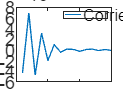

figure
plot(X(2,:));  
legend('Corriente 1')

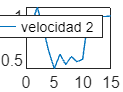


figure
plot(X(3,:))
legend('velocidad 2')

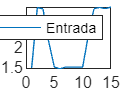


figure
plot(U(1,:));  
legend('Entrada')

function [X, U] = mpc_controller(A, B, C, D, Ts, N, Qy, R, yrefk, x0, Qf)
    sysc = ss(A, B, C, D);
    sysd = c2d(sysc, Ts, 'zoh');
    Ad = sysd.A;
    Bd = sysd.B;
    
    nx = size(A, 1); 
    nu = size(B, 2);
    ny = size(C, 1);

    % Función de costo
    Qbig = blkdiag(kron(eye(N), C' * Qy * C), kron(eye(N), R))

    Qbig(nx*(N-1)+(1:nx),nx*(N-1)+(1:nx)) = C'*Qy*C+C'*Qf*C
    
    % Asegurar que yrefk tenga dimensiones correctas
    if size(yrefk, 2) ~= 1
        error('yrefk debe ser un vector columna de tamaño (ny, 1)')
    end
    q = -[repmat(C' * Qy * yrefk, N, 1); zeros(N*nu, 1)];
    q(nx*(N-1)+(1:nx),1)=-C'*Qy*yrefk-C'*Qf*yrefk
    
    % Restricciones de igualdad 

    Aeq = zeros(N * nx, N * (nx + nu));
    beq = zeros(N * nx, 1);

    for k = 1:N
        Aeq((k-1)*nx+1:k*nx, (k-1)*nx+1:k*nx) = -eye(nx);
        if k == 1
            Aeq(1:nx, 1:nx) = -eye(nx);
            Aeq(1:nx, nx*N+1:nx*N+nu) = Bd;
            beq(1:nx) = -Ad * x0;
        else
            Aeq((k-1)*nx+1:k*nx, (k-2)*nx+1:(k-1)*nx) = Ad;
            Aeq((k-1)*nx+1:k*nx, nx*N+(k-1)*nu+1:nx*N+k*nu) = Bd;
        end
    end

    Aineq = [];
    bineq = [];

    %------------------------
    % Restricciones de control y estados
    Umax = [1.5]
    Umin = [0]

    Xmax = [0;4e-3;0];
    Xmin = [0;-2e-3;0];

    %--------------------------

    [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, [], Umax,5,10)
    
    % Resolver el problema de optimización cuadrática
    z = quadprog(Qbig, q, Aineq, bineq, Aeq, beq)

    X = reshape(z(1:nx*N), nx, N);
    U = reshape(z(nx*N+1:end), nu, N);
end
function [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax, sat_start, sat_end)
% RESTRICCIONES Construye las restricciones de desigualdad para un problema de MPC.
%
% La variable de optimización se organiza como:
%   z = [x0; x1; ...; x_{N-1}; u0; u1; ...; u_{N-1}]
%
% Entradas:
%   nx      - Número de estados del sistema.
%   nu      - Número de entradas del sistema.
%   N       - Horizonte de predicción (total de instantes).
%   Xmin    - Vector (nx x 1) con el límite inferior de cada estado.
%             Para ignorar este límite, pasar [].
%   Xmax    - Vector (nx x 1) con el límite superior de cada estado.
%             Para ignorar este límite, pasar [].
%             Si para cierto estado se tienen Xmax(i)==0 y Xmin(i)==0,
%             se ignoran las restricciones para ese estado.
%   Umin    - Vector (nu x 1) con el límite inferior de cada entrada.
%             Para ignorar este límite, pasar [].
%   Umax    - Vector (nu x 1) con el límite superior de cada entrada.
%             Para ignorar este límite, pasar [].
%             Si para cierta entrada se tienen Umax(j)==0 y Umin(j)==0,
%             se ignoran las restricciones para esa entrada.
%
%   sat_start - (Opcional) Instante inicial en el que se aplican las restricciones.
%               Por defecto se toma 1 (es decir, desde el inicio).
%   sat_end   - (Opcional) Instante final en el que se aplican las restricciones.
%               Por defecto se toma N (es decir, hasta el final).
%
% Salidas:
%   Aineq   - Matriz de restricciones de desigualdad.
%   bineq   - Vector de restricciones de desigualdad.
%
% Ejemplo:
%   % Para 4 estados y 2 entradas, con restricciones solo desde t = 3 hasta t = 8:
%   Xmax = [0; 1.02; 0.99; 0];
%   Xmin = [0; 0; 0; 0];
%   Umax = [50; []];   % Sólo se imponen restricciones en la primera entrada.
%   Umin = [0; []];
%   [Aineq, bineq] = restricciones(4, 2, 10, Xmin, Xmax, Umin, Umax, 3, 8);
%
%   Si no se especifican sat_start y sat_end, se saturan desde t = 1 hasta t = N:
%       [Aineq, bineq] = restricciones(4, 2, 10, Xmin, Xmax, Umin, Umax);

    % Parámetros opcionales: si no se proporcionan, se saturan desde el inicio hasta el final.
    if nargin < 8 || isempty(sat_start)
        sat_start = 1;
    end
    if nargin < 9 || isempty(sat_end)
        sat_end = N;
    end

    % Número total de variables:
    % Estados: nx * N, Entradas: nu * N.
    nvar = nx * N + nu * N;
    
    Aineq = [];
    bineq = [];
    
    %% Restricciones para los estados
    for t = 1:N
        % Aplicar restricciones solo si t está dentro del tramo definido:
        if t < sat_start || t > sat_end
            continue;
        end
        for i = 1:nx
            idx = (t-1)*nx + i; 
            % Restricción superior: x_i(t) <= Xmax(i)
            if ~isempty(Xmax)
                if ~( Xmax(i)==0 && ~isempty(Xmin) && Xmin(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Xmax(i)];
                end
            end

            % Restricción inferior: x_i(t) >= Xmin(i)
            if ~isempty(Xmin)
                if ~( Xmin(i)==0 && ~isempty(Xmax) && Xmax(i)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Xmin(i)];
                end
            end
        end
    end
    
    %% Restricciones para las entradas
    for t = 1:N
        % Aplicar restricciones solo si t está dentro del tramo definido:
        if t < sat_start || t > sat_end
            continue;
        end
        for j = 1:nu
            idx = nx * N + (t-1)*nu + j; 
            % Restricción superior: u_j(t) <= Umax(j)
            if ~isempty(Umax)
                if ~( Umax(j)==0 && ~isempty(Umin) && Umin(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = 1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; Umax(j)];
                end
            end
            
            % Restricción inferior: u_j(t) >= Umin(j)
            if ~isempty(Umin)
                if ~( Umin(j)==0 && ~isempty(Umax) && Umax(j)==0 )
                    row = zeros(1, nvar);
                    row(idx) = -1;
                    Aineq = [Aineq; row];
                    bineq = [bineq; -Umin(j)];
                end
            end
        end
    end
end


% % % function [Aineq, bineq] = restricciones(nx, nu, N, Xmin, Xmax, Umin, Umax)
% % %     nvar = nx * N + nu * N;
% % % 
% % %     Aineq = [];
% % %     bineq = [];
% % % 
% % %     %% Restricciones para los estados
% % %     for t = 1:N
% % %         for i = 1:nx
% % %             idx = (t-1)*nx + i; 
% % %             if ~isempty(Xmax)
% % %                 if ~( Xmax(i)==0 && ~isempty(Xmin) && Xmin(i)==0 )
% % %                     row = zeros(1, nvar);
% % %                     row(idx) = 1;
% % %                     Aineq = [Aineq; row];
% % %                     bineq = [bineq; Xmax(i)];
% % %                 end
% % %             end
% % % 
% % %             if ~isempty(Xmin)
% % %                 if ~( Xmin(i)==0 && ~isempty(Xmax) && Xmax(i)==0 )
% % %                     row = zeros(1, nvar);
% % %                     row(idx) = -1;
% % %                     Aineq = [Aineq; row];
% % %                     bineq = [bineq; -Xmin(i)];
% % %                 end
% % %             end
% % %         end
% % %     end
% % % 
% % %     %% Restricciones para las entradas
% % %     for t = 1:N
% % %         for j = 1:nu
% % %             idx = nx * N + (t-1)*nu + j; 
% % %             if ~isempty(Umax)
% % %                 if ~( Umax(j)==0 && ~isempty(Umin) && Umin(j)==0 )
% % %                     row = zeros(1, nvar);
% % %                     row(idx) = 1;
% % %                     Aineq = [Aineq; row];
% % %                     bineq = [bineq; Umax(j)];
% % %                 end
% % %             end
% % % 
% % %             if ~isempty(Umin)
% % %                 if ~( Umin(j)==0 && ~isempty(Umax) && Umax(j)==0 )
% % %                     row = zeros(1, nvar);
% % %                     row(idx) = -1;
% % %                     Aineq = [Aineq; row];
% % %                     bineq = [bineq; -Umin(j)];
% % %                 end
% % %             end
% % %         end
% % %     end
% % % end
